# Sum Diff Phase

clear all;

% chapter 7, 205p (7.66) Equ.
g0 = 1;                                     % constant
A = 1;                                      % amplitude of signal
c = 3*10^8;                                 % [m/s]
f = 300*10^6;                               % [Hz]           
lambda = c/f;                               % wavelength(파장) [m]
D = 1;                                      % aperture diameter(유효 안테나 직경)
theta3 = lambda/D                           % constant

theta3 = 1

theta_s = theta3/3                          % constant

theta_s = 0.3333

k = 4*(theta_s/theta3)*log2(2);             % constant
d = 1;                                      % distance of monopulse radar [m]
xi = 1;                                     % fixed phase error [deg]
theta_t = -asin(xi/(k*d));                  % chapter7, 202p (7.48) Equ.
km = 2*sqrt(2)*log2(2)*theta_s/theta3;      % anttena constant

% azi_angle과 elv_angle 임의로 설정
delta_time = 1;
max_time = 11;
for i = 1 : delta_time : max_time
    azi_angle(i) = (i-1)*0.5;
    elv_angle(i) = (-i+1)*0.5;
end

% AWGN channel
mu = 0; sigma = 0.043;
noise = mu + sigma*randn(length(azi_angle),1)';

% function G4를 이용하여 beam의 gain 계산
angle_length = length(azi_angle);
calculate_gain = Fn_AnttenaVoltagePattern4(g0, km, theta3, azi_angle, elv_angle);
gain = reshape(calculate_gain,[angle_length,4])

gain =     1.0000    1.0000    1.0000    1.0000
    1.0000    0.0572    1.0000    1.9428
    1.0000   -0.8856    1.0000    2.8856
    1.0000   -1.8284    1.0000    3.8284
    1.0000   -2.7712    1.0000    4.7712
    1.0000   -3.7140    1.0000    5.7140
    1.0000   -4.6569    1.0000    6.6569
    1.0000   -5.5997    1.0000    7.5997
    1.0000   -6.5425    1.0000    8.5425
    1.0000   -7.4853    1.0000    9.4853



% 추정된 theta_t_azi와 theta_t_elv 계산
% (Fig. 7.30), delta_az = 1/2[(a+d)-(b+c)], delta_el = 1/2[(a+b)-(c+d)]
for i = 1 : delta_time : max_time
    delta_theta_t_az(i) = noise(i) + (1/2)*((gain(i,1) + gain(i,4)) - (gain(i,2) + gain(i,3)));
    delta_theta_t_el(i) = noise(i) + (1/2)*((gain(i,1) + gain(i,2)) - (gain(i,3) + gain(i,4)));
    estimation_theta_t_az = delta_theta_t_az*theta3/(2*g0*km*A);   % estimation of theta_t_azi
    estimation_theta_t_el = delta_theta_t_el*theta3/(2*g0*km*A);   % estimation of theta_t_elv
end

% 추정한 위상각과 고도각 확인
estimation_theta_t_az

estimation_theta_t_az =     0.0123    0.5418    0.9485    1.5197    2.0073    2.4702    2.9901    3.5078    4.0816    4.5632    4.9692


estimation_theta_t_el

estimation_theta_t_el =     0.0123   -0.4582   -1.0515   -1.4803   -1.9927   -2.5298   -3.0099   -3.4922   -3.9184   -4.4368   -5.0308


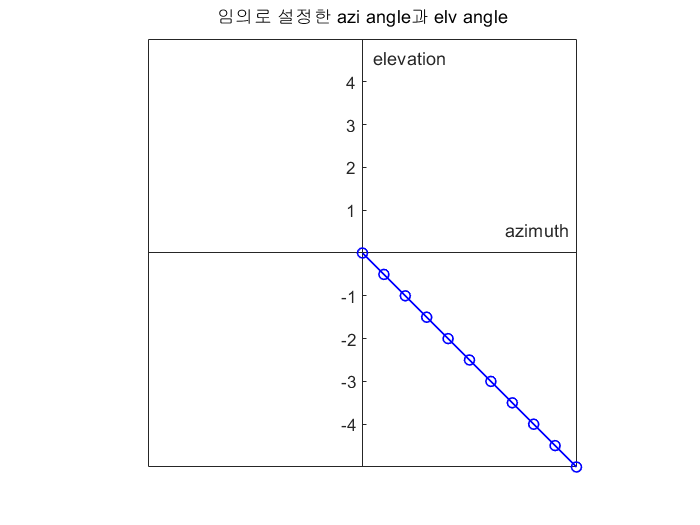


% 임의로 설정한 azi_angle과 elv_angle을 plot에 표시
plot(azi_angle, elv_angle, 'color', 'b', 'Marker', 'o','LineWidth', 1);
axis('square', [-5, 5, -5, 5]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title("임의로 설정한 azi_ angle과 elv_ angle");
xlabel('azimuth');
ylabel('elevation');

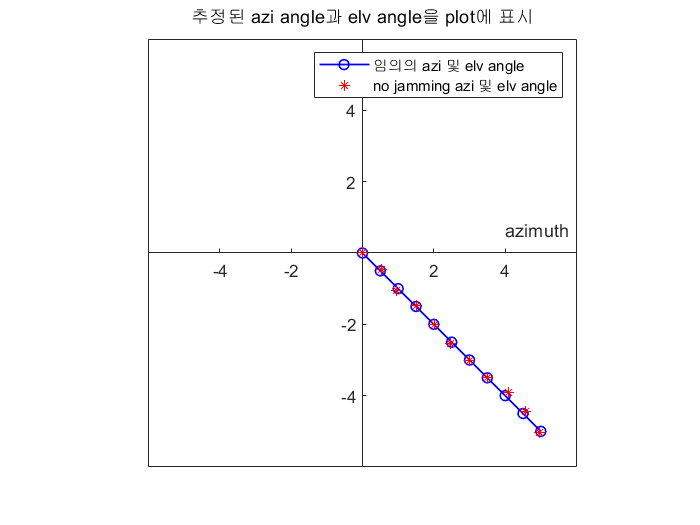


% 추정된 azi, elv를 추가로 plot에 표시
plot(azi_angle, elv_angle, 'color', 'b', 'Marker', 'o', 'LineWidth', 1);
axis('square', [-6, 6, -6, 6]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
title("추정된 azi_ angle과 elv_ angle을 plot에 표시");
xlabel('azimuth');
ylabel('elevation');
hold on
plot(estimation_theta_t_az, estimation_theta_t_el, 'color', 'r', 'Marker','*', 'LineStyle', 'none');
legend('임의의 azi 및 elv angle','no jamming azi 및 elv angle');

hold off

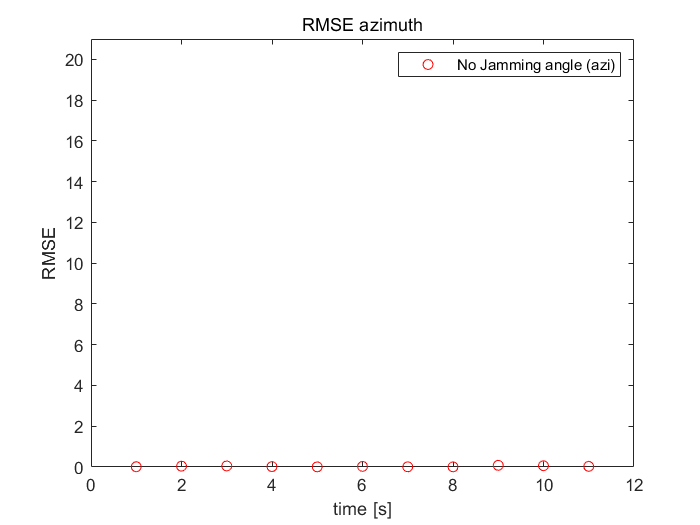


% RMSE
for i = 1 : delta_time : max_time
    RMSE_azi(i) = sqrt(mean((estimation_theta_t_az(i) - azi_angle(i)).^2));
    RMSE_elv(i) = sqrt(mean((estimation_theta_t_el(i) - elv_angle(i)).^2));
end
plot(RMSE_azi, 'color', 'r', 'Marker','o', 'LineStyle', 'none');
title('RMSE azimuth');
xlabel('time [s]');
ylabel('RMSE');
legend('No Jamming angle (azi)');
axis([0 max_time+1 0 max_time+10]);

RMSE_azi

RMSE_azi =     0.0123    0.0418    0.0515    0.0197    0.0073    0.0298    0.0099    0.0078    0.0816    0.0632    0.0308


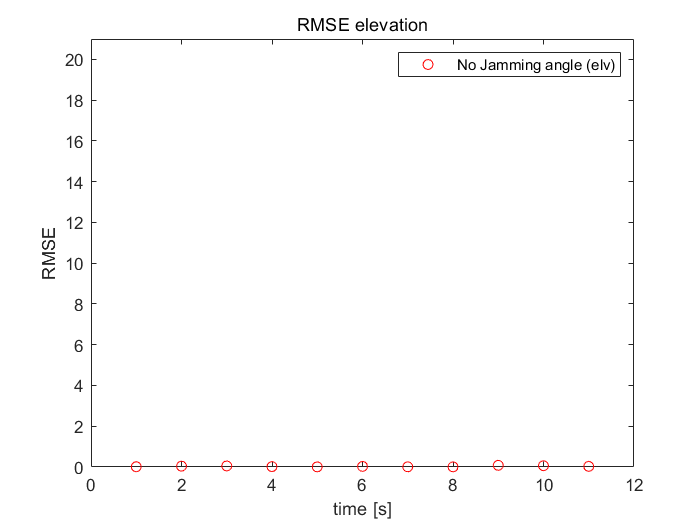


plot(RMSE_elv, 'color', 'r', 'Marker','o', 'LineStyle', 'none');
title('RMSE elevation');
xlabel('time [s]');
ylabel('RMSE');
legend('No Jamming angle (elv)');
axis([0 max_time+1 0 max_time+10]);

RMSE_elv

RMSE_elv =     0.0123    0.0418    0.0515    0.0197    0.0073    0.0298    0.0099    0.0078    0.0816    0.0632    0.0308


% ----------------------------------------------------------------
% --------------------------- jamming ----------------------------
% ----------------------------------------------------------------

calculate_polar_gain = Fn_AnttenaVoltagePattern5(g0, km, theta3, azi_angle, elv_angle);
polar_gain = reshape(calculate_polar_gain,[angle_length,4])

polar_gain =    -1.0000    1.0000   -1.0000    1.0000
   -1.0000    0.0572   -1.0000    1.9428
   -1.0000   -0.8856   -1.0000    2.8856
   -1.0000   -1.8284   -1.0000    3.8284
   -1.0000   -2.7712   -1.0000    4.7712
   -1.0000   -3.7140   -1.0000    5.7140
   -1.0000   -4.6569   -1.0000    6.6569
   -1.0000   -5.5997   -1.0000    7.5997
   -1.0000   -6.5425   -1.0000    8.5425
   -1.0000   -7.4853   -1.0000    9.4853


A = 1;
for i = 1 : delta_time : max_time
    polar_delta_theta_t_az(i) = noise(i) + (1/2)*((polar_gain(i,2) + polar_gain(i,3)) - (polar_gain(i,1) + polar_gain(i,4)));
    polar_delta_theta_t_el(i) = noise(i) + (1/2)*((polar_gain(i,3) + polar_gain(i,4)) - (polar_gain(i,1) + polar_gain(i,2)));
    polar_estimation_theta_t_az = polar_delta_theta_t_az*theta3/(2*g0*km*A);   % estimation of polar_theta_t_azi
    polar_estimation_theta_t_el = polar_delta_theta_t_el*theta3/(2*g0*km*A);   % estimation of polar_theta_t_elv
end
A=3

A = 3

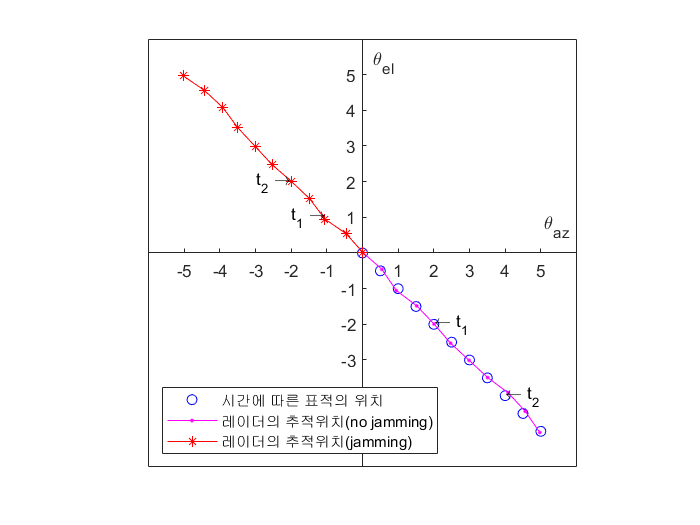

for i = 1 : delta_time : max_time
    polar_delta_theta_t_az(i) = noise(i) + (1/2)*((polar_gain(i,2) + polar_gain(i,3)) - (polar_gain(i,1) + polar_gain(i,4)));
    polar_delta_theta_t_el(i) = noise(i) + (1/2)*((polar_gain(i,3) + polar_gain(i,4)) - (polar_gain(i,1) + polar_gain(i,2)));
    polar_estimation_theta_t_az3 = polar_delta_theta_t_az*theta3/(2*g0*km*A);   % estimation of polar_theta_t_azi
    polar_estimation_theta_t_el3 = polar_delta_theta_t_el*theta3/(2*g0*km*A);   % estimation of polar_theta_t_elv
end
% 추정된 azi, elv를 추가로 plot에 표시
plot(azi_angle, elv_angle, 'color', 'b', 'Marker', 'o','LineStyle', 'none');
axis('square', [-6, 6, -6, 6]);
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
%title("azimuth, elevation angle (A=3)");
xlabel('\theta_a_z');
ylabel('\theta_e_l');
xticks([-5 -4 -3 -2 -1 0 1 2 3 4 5]);
yticks([-5 -4 -3 -2 -1 0 1 2 3 4 5]);
hold on
plot(estimation_theta_t_az, estimation_theta_t_el, 'color', 'm', 'Marker','.', 'LineStyle', '-');
plot(polar_estimation_theta_t_az, polar_estimation_theta_t_el, 'color', 'r', 'Marker','*', 'LineStyle', '-');
legend('시간에 따른 표적의 위치','레이더의 추적위치(no jamming)', '레이더의 추적위치(jamming)',"location","southwest");
text(2,-2,'\leftarrow t_1');
text(4,-4,'\leftarrow t_2');
text(-2,1,'t_1 \rightarrow');
text(-3,2,'t_2 \rightarrow');
hold off


% RMSE
t = 0 : delta_time : max_time-1

t =      0     1     2     3     4     5     6     7     8     9    10


for i = 1 : delta_time : max_time
    polar_RMSE_azi(i) = sqrt(mean((polar_estimation_theta_t_az(i) - azi_angle(i)).^2))+noise(i);
    polar_RMSE_elv(i) = sqrt(mean((polar_estimation_theta_t_el(i) - elv_angle(i)).^2));
end
for i = 1 : delta_time : max_time
    polar_RMSE_azi3(i) = sqrt(mean((polar_estimation_theta_t_az3(i) - azi_angle(i)).^2))+noise(i);
    polar_RMSE_elv3(i) = sqrt(mean((polar_estimation_theta_t_el3(i) - elv_angle(i)).^2));
end
length(polar_RMSE_azi)

ans = 11

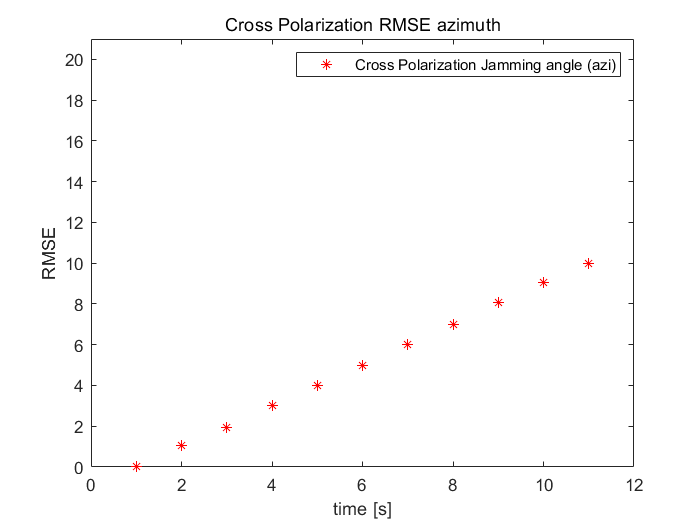

plot(polar_RMSE_azi, 'color', 'r', 'Marker','*', 'LineStyle', 'none');
title('Cross Polarization RMSE azimuth');
xlabel('time [s]');
ylabel('RMSE');
legend('Cross Polarization Jamming angle (azi)');
axis([0 max_time+1 0 max_time+10]);

polar_RMSE_azi

polar_RMSE_azi =     0.0354    1.0370    1.9544    3.0174    4.0064    4.9736    5.9912    7.0069    8.0723    9.0559    9.9727


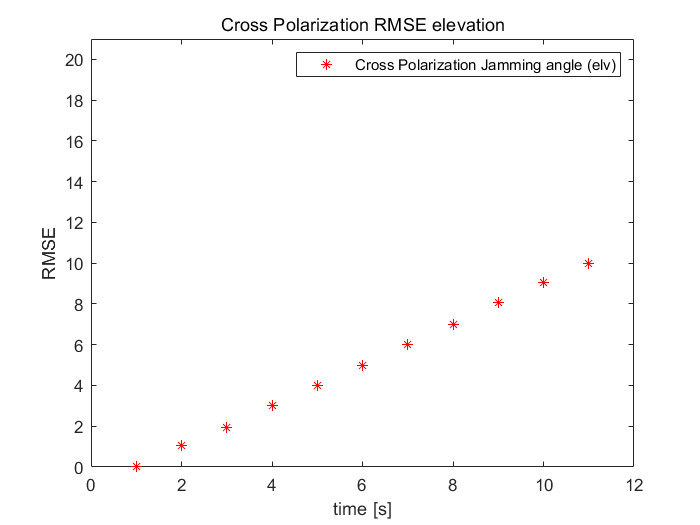


plot(polar_RMSE_elv, 'color', 'r', 'Marker','*', 'LineStyle', 'none');
title('Cross Polarization RMSE elevation');
xlabel('time [s]');
ylabel('RMSE');
legend('Cross Polarization Jamming angle (elv)');
axis([0 max_time+1 0 max_time+10]);

polar_RMSE_elv

polar_RMSE_elv =     0.0123    1.0418    1.9485    3.0197    4.0073    4.9702    5.9901    7.0078    8.0816    9.0632    9.9692


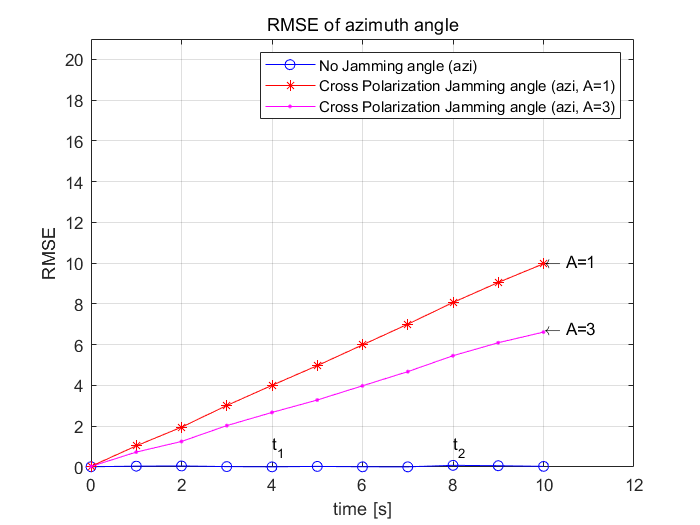


% --------------------graph 겹쳐 그리기-------------------
plot(t, RMSE_azi, 'color', 'b', 'Marker','o', 'LineStyle', '-');
hold on;
plot(t, polar_RMSE_azi, 'color', 'r', 'Marker','*', 'LineStyle', '-');
plot(t, polar_RMSE_azi3, 'color', 'm', 'Marker','.', 'LineStyle', '-');
title('RMSE of azimuth angle');
xlabel('time [s]');
ylabel('RMSE');
legend('No Jamming angle (azi)','Cross Polarization Jamming angle (azi, A=1)','Cross Polarization Jamming angle (azi, A=3)');
grid on
text(10,10.1,'\leftarrow A=1');
text(10,6.8,'\leftarrow A=3');
text(4,1,'t_1');
text(8,1,'t_2');
axis([0 max_time+1 0 max_time+10]);
hold off;

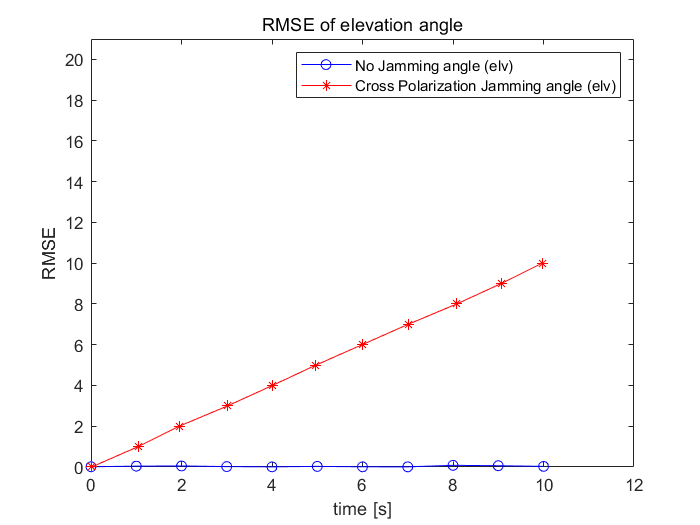


plot(t, RMSE_azi, 'color', 'b', 'Marker','o', 'LineStyle', '-');
hold on;
plot(polar_RMSE_elv, t, 'color', 'r', 'Marker','*', 'LineStyle', '-');
title('RMSE of elevation angle');
xlabel('time [s]');
ylabel('RMSE');
legend('No Jamming angle (elv)','Cross Polarization Jamming angle (elv)');
axis([0 max_time+1 0 max_time+10]);
hold off;

function

chapter7, 206p (7.68),(7.69) Equ. the two antenna voltage patterns & 213p (7.93) Equ.  

function G3 = Fn_AnttenaVoltagePattern3(g0, azi_angle, elv_angle, theta3, theta_s, k1, theta_t)

g1 = g0*exp(-k1*((theta_s/theta3) - (theta_t/theta3)).^2 * (azi_angle + elv_angle)/theta3);
g2 = g0*exp(-k1*((theta_s/theta3) + (theta_t/theta3)).^2 * (azi_angle - elv_angle)/theta3);
g3 = g0*exp(-k1*((theta_s/theta3) - (theta_t/theta3)).^2 * (-azi_angle - elv_angle)/theta3);
g4 = g0*exp(-k1*((theta_s/theta3) + (theta_t/theta3)).^2 * (-azi_angle + elv_angle)/theta3);

G3 = [g1, g2, g3, g4];
end

function G4 = Fn_AnttenaVoltagePattern4(g0, km, theta3, azi_angle, elv_angle)

g1 = g0*(1 + km * ((azi_angle + elv_angle)/theta3));
g2 = g0*(1 + km * ((elv_angle - azi_angle)/theta3));
g3 = g0*(1 - km * ((elv_angle + azi_angle)/theta3));
g4 = g0*(1 + km * ((azi_angle - elv_angle)/theta3));

G4 = [g1, g2, g3, g4];
end

function G5 = Fn_AnttenaVoltagePattern5(g0, km, theta3, azi_angle, elv_angle)
kp_1theta = 1;  kp_2theta = -1;  kp_3theta = -1;  kp_4theta = 1;
kp_1psi = 1;  kp_2psi = 1;  kp_3psi = -1;  kp_4psi = -1;
% kp_1theta = 0;  kp_2theta = 0;  kp_3theta = 0;  kp_4theta = 0;
% kp_1psi = 0;  kp_2psi = 0;  kp_3psi = 0;  kp_4psi = 0;

g1 = g0*(1 + km * ((azi_angle + elv_angle)/theta3));
g2 = g0*(1 + km * ((elv_angle - azi_angle)/theta3));
g3 = g0*(1 - km * ((elv_angle + azi_angle)/theta3));
g4 = g0*(1 + km * ((azi_angle - elv_angle)/theta3));

g_p1 = -g1.*(1 + kp_1theta*elv_angle + kp_1psi*azi_angle);
g_p2 = g2.*(1 + kp_2theta*elv_angle - kp_2psi*azi_angle);
g_p3 = -g3.*(1 - kp_3theta*elv_angle - kp_3psi*azi_angle);
g_p4 = g4.*(1 - kp_4theta*elv_angle + kp_4psi*azi_angle);

G5 = [g_p1, g_p2, g_p3, g_p4];
end